%define the value of the function y using cubic.exe

syms x;
y = 4*x^3 + 16*x^2 + 2*x + 2

$$y = 4\,x^{3}+16\,x^{2}+2\,x+2$$

%look for the  real roots of the function

R_roots = double(solve(y,'Real',true))

R_roots = -3.9047

%find stationary points

dy = diff(y)

$$dy = 12\,x^{2}+32\,x+2$$

d2y = diff(dy)

$$d2y = 24\,x+32$$


%stationary points coordinates
sX = double(solve(dy==0))

sX =    -2.6026
   -0.0640


sY = double(subs(y,sX))

sY =    34.6561
    1.9365



%label them as minimum or maximum
for i=1:length(sX)
    if double(subs(d2y,sX(i)))>0
        min = double([sX(i),subs(y,sX(i))])
    else if double(subs(d2y,sX(i)))<0
        max = double([sX(i),subs(y,sX(i))])
    end
    end
end

max =    -2.6026   34.6561


min =    -0.0640    1.9365


%plot the polynomial, stationairy points and legend
points=[R_roots,0,max,min] 

points =    -3.9047         0   -2.6026   34.6561   -0.0640    1.9365


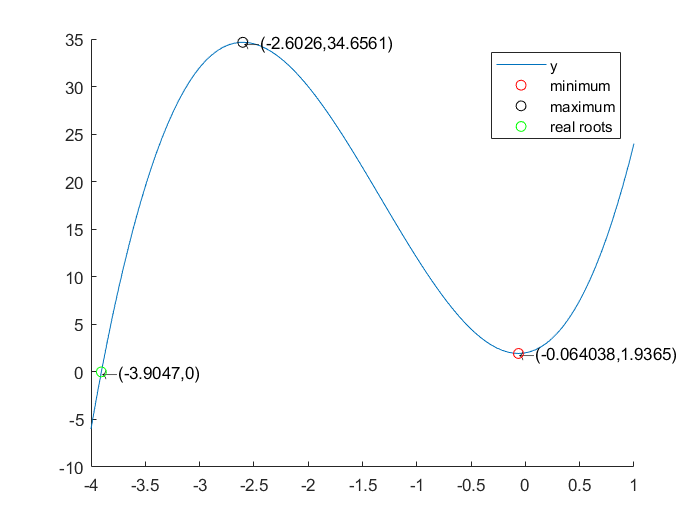


hold on
plot(linspace(-4,1),subs(y,linspace(-4,1)))
for k=1:2:(length(points)-1)
      text(points(k),points(k+1),['\leftarrow' '(' num2str(points(k)) ',' num2str(points(k+1)) ')'])
end
scatter(min(1),min(2),"red")
scatter(max(1),max(2),"black")
scatter(R_roots,0,"green")
legend({"y","minimum","maximum","real roots"})
hold off

%compute the definite integral

clf
a=-1%there is one root, so this is second limit of integration

a = -1

int(y,x)%formula for definite integral

$$ans = x^{4}+\frac{16\,x^{3}}{3}+x^{2}+2\,x$$

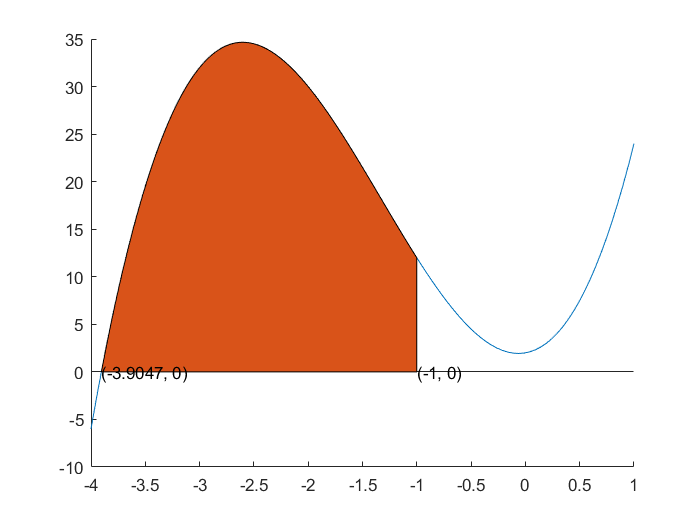


hold on
plot(linspace(-4,1),subs(y,linspace(-4,1)));
int_range=linspace(R_roots,a);
area(int_range,subs(y,int_range))%color the area under y within limits of integration

%show the limits on the plot
text(R_roots,0,['(', num2str(R_roots), ', ', num2str(0), ')'])
text(a,0,['(', num2str(a), ', ', num2str(0), ')'])


double(int(y,R_roots,a))

ans = 72.2812